% 1st order
clc; clear; close all
tic
format long

%% parameter settings
tol = 1e-5;
kmax = 3000;
N = 129;
x = linspace(0, 1, N);
z = linspace(0, 1, N);
[X, Z] = meshgrid(x, z);

%% examples
c_exact = 0.5-0.5*(Z-0.5);

%% source point
fixed_pt_list = [];
for m = 1:4
    for n = 1:4
        fixed_pt_list = [fixed_pt_list; 0, m*25, n*25];
    end
end 


%% iteration
I = N;
J = N;
dx = (x(end)-x(1)) / (I-1); dy = (z(end) - z(1)) / (J-1);

niu = 1;
c0 = c_solver2(c_exact, zeros(I, J), dx, dy, niu);
c = c0;

energy = 1e9;
relative_error = 1e9;
% alpha_f = 1e-4; alpha_0 = 0.1;
for k = 1: kmax
    
    energy_p = 0;
    cstar = 0;
    parfor p_num = 1:size(fixed_pt_list, 1)
        T = TravelTime_solver(c, fixed_pt_list(p_num, :), dx, dy, I, J);
        T_star = TravelTime_solver(c_exact, fixed_pt_list(p_num, :), dx, dy, I, J);
        energy_p = energy_p + EnergyFun(T, T_star, dx, dy);
        cstar = cstar + cStarSolver(T, T_star, dx, I, J, c);
    end
    
    if norm(cstar)*dx*dy < tol
        break
    end

    energy = [energy, energy_p];
    relative_error = [relative_error, norm(c-c_exact)/norm(c_exact)];
    if mod(k, 10) == 0
       disp(k)
       disp(norm(cstar)*dx*dy)
    end

        alpha = 0.01;
    c = c + alpha * cstar;
   
end

    10


     2.360584073395282e-04


    20


     1.290287536725242e-04


    30


     7.783963943508139e-05


    40


     4.905583107648805e-05


    50


     3.247908596818987e-05


    60


     2.271460880969418e-05


    70


     1.680023945034930e-05


    80


     1.307668519612132e-05


    90


     1.061165182171725e-05



%% results and visualization
norm(c-c_exact)*dx*dx

ans =      1.121839072197982e-05

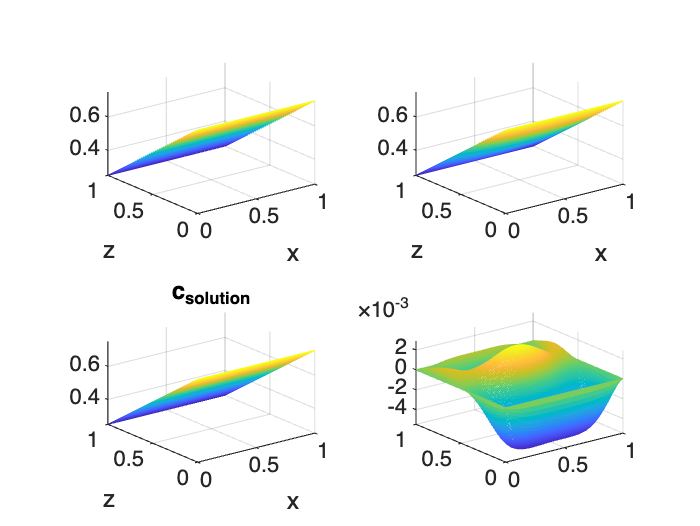


figure
subplot(2, 2, 1)
mesh(x, z, c_exact)
xlabel x
ylabel z
% title('c_{exact}', 'FontWeight','bold')
subplot(2, 2, 2)
mesh(x, z, c0)
xlabel x
ylabel z
% title('c_0', 'FontWeight','bold')
subplot(2, 2, 3)
mesh(x, z, c)
xlabel x
ylabel z
title('c_{solution}', 'FontWeight','bold')
subplot(2, 2, 4)
mesh(x, z, (c-c_exact)./c_exact)

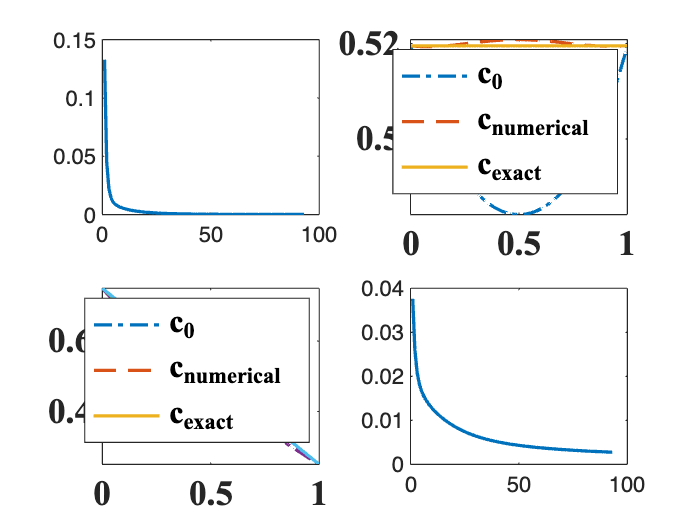

% title('Relative error')

figure
subplot(2, 2, 1)
plot(energy(2:end), 'linewidth', 1.5)
% title('Energy')

subplot(2, 2, 2)
plot(z, c0(60, :), '-.', 'linewidth', 1.5)
hold on
plot(z, c(60, :), '--', 'linewidth', 1.5)
hold on
plot(z, c_exact(60, :), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
% title('Cross-sections of the solutions: x = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');

subplot(2, 2, 3)
plot(x, c0(:, 60), '-.', 'linewidth', 1.5)
hold on
plot(x, c(:, 60), '--', 'linewidth', 1.5)
hold on
plot(x, c_exact(:, 60), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
% title('Cross-sections of the solutions: z = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');

subplot(2, 2, 3)
plot(x, c0(:, 60), '-.', 'linewidth', 1.5)
hold on
plot(x, c(:, 60), '--', 'linewidth', 1.5)
hold on
plot(x, c_exact(:, 60), 'linewidth', 1.5)
legend('c_0', 'c_{numerical}', 'c_{exact}')
% title('Cross-sections of the solutions: z = 0', 'FontWeight','bold')
set(gca, 'FontName','Times New Roman', 'FontSize',16, 'FontWeight','bold');
subplot(2, 2, 4)
plot(relative_error(2:end), 'linewidth', 1.5)

% title('Relative error')
toc

历时 13.810632 秒。
